x = 159;
a = 1+mod(x,3);
Wp = 10/360;
Ws = 20/360;
[n,wn] = buttord(Wp,Ws,a,40)

n = 8

wn = 0.0313

[b,c] = butter(n,wn);
sys = tf(b,c,(1/720))

sys =
 
                                                                                                                                
  2.668e-11 z^8 + 2.134e-10 z^7 + 7.47e-10 z^6 + 1.494e-09 z^5 + 1.867e-09 z^4 + 1.494e-09 z^3 + 7.47e-10 z^2 + 2.134e          
                                                                                                                                
                                                                                                               -10 z + 2.668e-11
                                                                                                                                
  ------------------------------------------------------------------------------------------------------------------------------
                                                                                                               
                   z^8 - 7.496 z^7 + 24.6 z^6 - 46.15 z^5 + 54.15 z^4 - 40.69 z^3 + 19.12 z^2 - 5.136 z + 

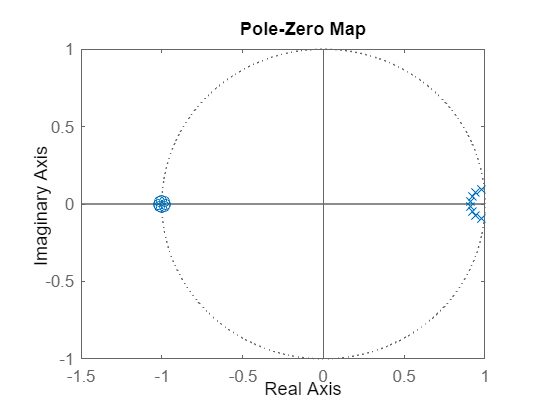

w = linspace(0,360,1000);

pzmap(sys)

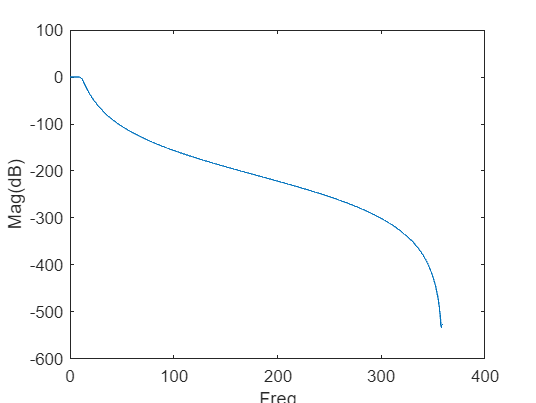


[Mag,Phase] = bode(sys,2*pi*w);
plot(w,db(squeeze(Mag)))
xlabel('Freq')
ylabel('Mag(dB)')

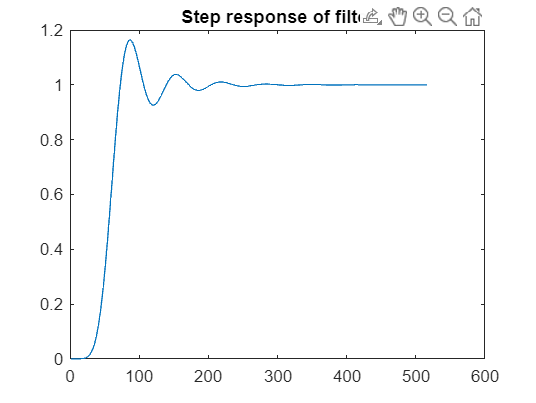


plot(stepz(b,c))
title('Step response of filter')

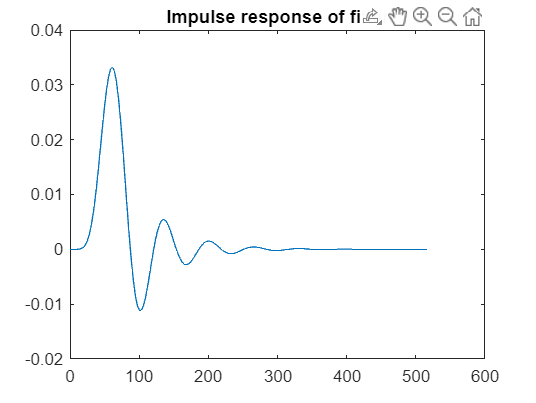


plot(impz(b,c))
title('Impulse response of filter')